## **Load ECG Data, Find R-peaks, Calculate R-R Intervals**

clear, clc
load('mitdb_dataset.mat')
load('em_noise.mat')
%Contains ecg signals (ecg) ; Sample rates (Fs)
rrInterval = cell(23,1);
qrs_amp_raw = cell(23,1);
rr_tm_mit = cell(23,1);
delay = cell(23,1);

for i = 1:23 % DEPENDENCY ON TOOLBOX CONTAINING PAN_TOMPKIN2
    [qrs_amp_raw{i,1},rr_tm_mit{i,1},delay{i,1}] = pan_tompkin2(ecg{i,1},Fs(i));
    rrInterval{i,1} = zeros(1,length(rr_tm_mit{i,1})-1);
    for z = 1:length(rrInterval{i,1})-1
        rrInterval{i,1}(z) = rr_tm_mit{i,1}(z+1) - rr_tm_mit{i,1}(z);
    end
end

## **Noise Generation and Data Pre-Processing**

%{
[noisy1_12, targNoiseSigma1_1] = createSignalPlusNoise(ecg{1,1},12);
[noisy1_6, ~] = createSignalPlusNoise(ecg{1,1},6);
[noisy4_12, ~] = createSignalPlusNoise(ecg{4,1},12);
%}
MSE_imp = zeros(1,20);
MSE = MSE_imp;
MAE = MSE_imp;
MSE_noise = MSE_imp;
MAE_noise = MSE_imp;
Variances = zeros(20,643);
Variances2 = zeros(20,643); %Use with Record 4

SNRs = zeros(1,20);
emScalings = zeros(1,20);
for iii = 10
    recNum = 4; %Can select number between 1 and 23 to access MIT database
    snr =  22-iii;
    emScale = (iii-1)/20;

    SNRs(iii) = snr;
    emScalings(iii)=emScale;
    [noisyECG, ~] = createSignalPlusNoise(ecg{recNum,1},snr);

    noisyECG2 = ecg{recNum,1}+emScale*em_noise;

    %ecgRecord = ecg{recNum,1}'; % Accesses the desired ECG signal
    ecgRecord = noisyECG;
    ecgRecord2 = noisyECG2;
    theseRRintervals = rrInterval{recNum,1}; % 
    medianSegLength = median(theseRRintervals);
    mu_moving = movmean(ecgRecord,medianSegLength/(2));
    mu_moving2 = movmean(ecgRecord2,medianSegLength);
    data = ecgRecord - mu_moving;
    data2 = ecgRecord2 - mu_moving2;
    %n = length(data);
    rPeakStamps = rr_tm_mit{recNum,1};
    %numSegments = length(rPeakStamps);
    numSegments = length(rPeakStamps)-1;
    segmentLength = max(theseRRintervals) + ceil(medianSegLength /2);
    segments = nan(numSegments,segmentLength);
    segments2 = segments;
    startstopIndices = zeros(2,numSegments);
    
    ecgStart = 1;
    ecgEnd = rPeakStamps(1) + floor((rPeakStamps(2) - rPeakStamps(1))/2);
    ecgLength = ecgEnd - ecgStart + 1;
    delta = segmentLength - ecgLength;
    segment = data(ecgStart:ecgEnd);
    segment2 = data2(ecgStart:ecgEnd);
    segStart = floor(delta/2);
    segEnd = segmentLength - ceil(delta/2) - 1;
    %segment(floor(delta/2)+1:segmentLength-ceil(delta/2)) = data(ecgStart:ecgEnd);
    startstopIndices(:,1) = [segStart;segEnd];
    segments(1,segStart:segEnd) = segment;
    segements2(1,segStart:segEnd) = segment2;
    


    for i = 2:numSegments-1
        segment = [];
        %end_index = rPeakStamps(i) + ceil(segmentLength/2) - 1;
        ecgStart = ecgEnd+1;
        %ecgEnd = rPeakStamps(i) + floor((rPeakStamps(i+1)-rPeakStamps(i))/2) ;
        ecgEnd = rPeakStamps(i) + ceil((rPeakStamps(i+1) - rPeakStamps(i))/2);
        ecgLength = ecgEnd - ecgStart + 1;
        delta = segmentLength - ecgLength;
        
        segment = data(ecgStart:ecgEnd);
        segment2 = data2(ecgStart:ecgEnd);
        segStart = floor(delta/2);
        segEnd = segmentLength - ceil(delta/2) - 1;
        startstopIndices(:,i) = [segStart;segEnd];
        segments(i, segStart:segEnd) = segment;
        segments2(i,segStart:segEnd) = segment2;
    end
    
    i = i+1;
    ecgStart = ecgEnd+1;
    ecgEnd = rPeakStamps(i) + ceil((rPeakStamps(i+1) - rPeakStamps(i))/2);
    %ecgEnd = n;
    ecgLength = ecgEnd - ecgStart + 1;
    delta = segmentLength - ecgLength;
    segment = data(ecgStart:ecgEnd);
    segment2 = data2(ecgStart:ecgEnd);
    segStart = floor(delta/2);
    segEnd = segmentLength - ceil(delta/2) - 1;
    startstopIndices(:,end) = [segStart;segEnd];
    segments(end,segStart : segEnd) = segment;
    segments2(end,segStart:segEnd) = segment2;

    row_means = mean(segments,2,'omitnan');
    row_means2 = mean(segments2,2,'omitnan');
    X_centered = segments - row_means;
    X_centered2 = segments2 - row_means2;
    X_centered = fillmissing(X_centered,'constant',0);
    X_centered2 = fillmissing(X_centered2,'constant',0);
    [centeredSegments, refTimes] = ecgsCentered(X_centered,startstopIndices);
    [centeredSegments2, refTimes2] = ecgsCentered(X_centered2,startstopIndices);


## **Perform PCA on Processed Data - Take top Principal Component**

    [Y_pca,score,latent,tsquared,explained,mu] = pca(centeredSegments);

    [Y_pca2,score2,latent2,~,explained2,mu2] = pca(centeredSegments2);

    Variances(iii,1:length(explained)) = explained';
    Variances2(iii,1:length(explained2)) = explained2';
    P=1;    
    pcaDenoised = score(:,1:P) * Y_pca(:,1:P)' + row_means + mu;
    pcaDenoised2 = score2(:,100:end) * Y_pca2(:,100:end)' + mu2 + row_means;

    %{
    figure()
    subplot(1,2,1)
    plot(1:segmentLength,pcaDenoised(1:12,:))
    xlabel('t')
    ylabel('mag')
    title('Princ Component Representation')
    subplot(1,2,2)
    plot(1:segmentLength,centeredSegments(1:12,:))
    %}

## Reconstruct the De-noised signal from R-R Segments

    sigDenoised = [];
    sigDenoised2 = [];
    for i = 1:numSegments
        segStart = startstopIndices(1,i);
        segEnd = startstopIndices(2,i);

        %Reconstruct de-noised signal by piecing together individual
        %segments
        sigDenoised = [sigDenoised, pcaDenoised(i,segStart:segEnd)];
        sigDenoised2 = [sigDenoised2, pcaDenoised2(i,segStart:segEnd)];
    end
    n=length(sigDenoised);
    sigDenoised = sigDenoised + mu_moving(1:n)'; %Add back the moving mean
    sigDenoised2 = sigDenoised2 + mu_moving2(1:n)';

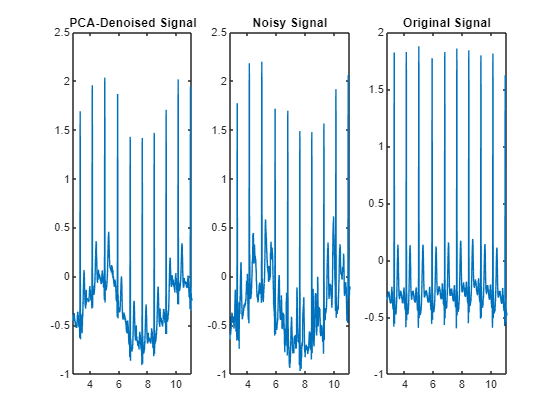

    sampInterval2Plot = 1001:4000; %Pick a time interval to plot (in samples)
    timeInterval2Plot = tm{recNum,1}(sampInterval2Plot); %Convert to time (in seconds)
    
    figure()
    subplot(1,3,1)

    plot(timeInterval2Plot,sigDenoised2(sampInterval2Plot))
    title('PCA-Denoised Signal')
    subplot(1,3,2)
    plot(timeInterval2Plot,ecgRecord2(sampInterval2Plot))
    title('Noisy Signal')
    subplot(1,3,3)
    plot(timeInterval2Plot,ecg{recNum,1}(sampInterval2Plot))
    title('Original Signal')
    


%% ERROR COMPARISIONS
    %{
    %Compare Denoised Signal to Ground Truth
    delta = abs(sigDenoised - ecg{recNum,1}(1:length(sigDenoised))');
    
    %Compare Ground Truth to Noisy Signal
    
    deltaNoise = abs(ecg{recNum,1}(1:length(sigDenoised)) - ecgRecord(1:length(sigDenoised)));
    deltaSquare = delta.^2;
    deltaNoiseSquare = deltaNoise.^2;
    MSE(iii) = 1/n * sum(deltaSquare);
    MAE(iii) = 1/n* sum(delta);
    MSE_noise(iii) = 1/n * sum(deltaNoiseSquare);
    MAE_noise(iii) = 1/n * sum(deltaNoise);
    MSE_imp(iii) = 10*log10(MSE_noise/MSE);
    num4title = num2str(recNum);
    snr4title = num2str(snr);
    tHead = strcat("PCA Performance: ",snr4title,"db SNR");
    tSub = strcat('Record'," ",num4title);
    figure(6)
    sgtitle(tHead)
    subplot(5,4,iii)
    plot(timeInterval2Plot,ecgRecord(sampInterval2Plot))
    hold on
    plot(timeInterval2Plot,ecg{recNum,1}(sampInterval2Plot))
    plot(timeInterval2Plot,sigDenoised(sampInterval2Plot))
    xlabel('time (s)')
    ylabel('Amplitude')
    legend('Noisy','Original','PCA De-noised')
    title(tSub)
    %}
end
    

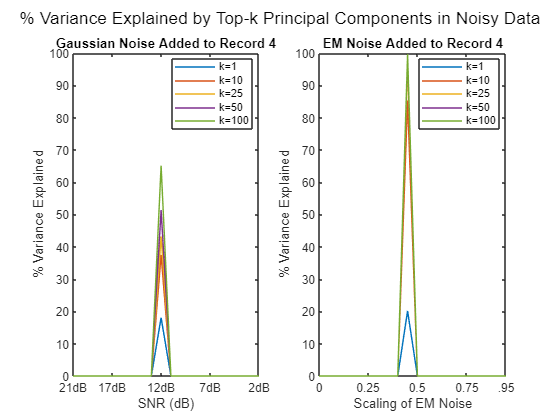


%figure
%plot(1:15,MAE(1:15))
lambdas = zeros(1,15);

for i = 1:length(lambdas)
    lambdas(i) = 1/i;
end
kVals = [1 10 25 50 100];
kFracs = zeros(20,length(kVals));
kFracs2 = zeros(20,length(kVals));
for k = 1:length(kVals)
    kFracs(:,k) = sum(Variances(:,1:kVals(k)),2);
    kFracs2(:,k) = sum(Variances2(:,1:kVals(k)),2);
end
figure
subplot(1,2,1)
sgtitle('% Variance Explained by Top-k Principal Components in Noisy Data')
plot(1:length(SNRs),kFracs')
legend('k=1','k=10','k=25','k=50','k=100','Location','best')
xlim([1 20])
xticks([1 5 10 15 20])
xticklabels({'21dB','17dB','12dB','7dB','2dB'})
xlabel('SNR (dB)')
title('Gaussian Noise Added to Record 4')
ylabel('% Variance Explained')
ylim([0 100])

subplot(1,2,2)
ylim([0 100])
plot(1:20,kFracs2)
xlabel('Scaling of EM Noise')
xlim([1 20])
xticks([1 6 11 16 20])
xticklabels({'0','0.25','0.5','0.75','.95'})
ylabel('% Variance Explained')
legend('k=1','k=10','k=25','k=50','k=100','Location','best')
title('EM Noise Added to Record 4')

%{
hold off
load("varExplained_record4.mat")
% Load to plot Variance Explained of MIT Record 4
figure
subplot(1,2,1)
sgtitle('Record 4: % Variance Explained by Top-k Principal Components')
plot(SNRs,fracOfVar100*100)
hold on
plot(SNRs,fracOfVar50*100)
plot(SNRs,fracOfVar25*100)
plot(SNRs,fracOfVar10*100)
plot(SNRs,Variances(:,1))
legend('k=100','k=50','k=25','k=10','k=1','Location','best')
xlabel('SNR of Noisy Data (dB)')
%xlim([1 20])
%xticks([1 5 10 15 20])
ylabel('% Variance Explained')
title('Gaussian Noise w/ Varying SNR')
hold off
subplot(1,2,2)
fracClean = zeros(1,100);
for i = 1:length(fracClean)
    fracClean(i) = sum(explained(1:i));
end
plot(1:100 , fracClean)
xlabel('k Principal Components')
xlim([0 100])
xticks([1 25 50 75 100])
ylabel('% Variance Explained')
title('Original (Clean) Recording')
%}